x1 = 1.2;
x2 = 1.2;
alpha = 1;
c1 = 1e-4;
gamma = 1e-1;
gradients = [];
steps = [];
gradient = 0.1;
while norm(gradient,'inf') > 1e-4
    step = alpha;
    gradient = [-400*(x2-x1^2)*(x1)-2*(1-x1); 200*(x2-x1^2)];
    newx1 = x1 - step * gradient(1);
    newx2 = x2 - step * gradient(2);
    while objective(newx1, newx2) > objective(x1,x2) + c1 * step * gradient' * -gradient
        step = step * gamma;
        newx1 = x1 - step * gradient(1);
        newx2 = x2 - step * gradient(2);
    end
    x1 = newx1;
    x2 = newx2;
    steps = [steps, step];
    %pause(0.1)
    norm_grad = norm(gradient, "inf");
    gradients = [gradients, norm_grad];
end
x1

x1 = 1.0000

x2

x2 = 1.0001

objective(x1,x2)

ans = 3.6146e-09

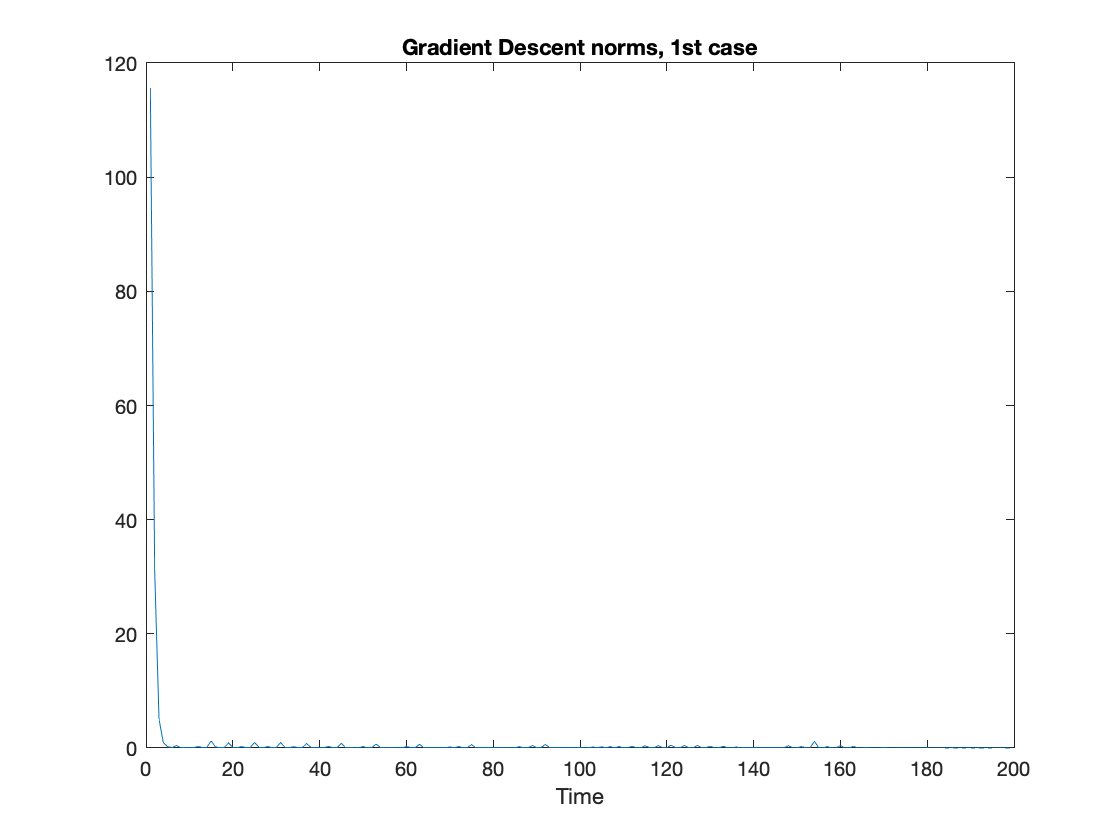

plot(gradients);xlabel('Time');title('Gradient Descent norms, 1st case');

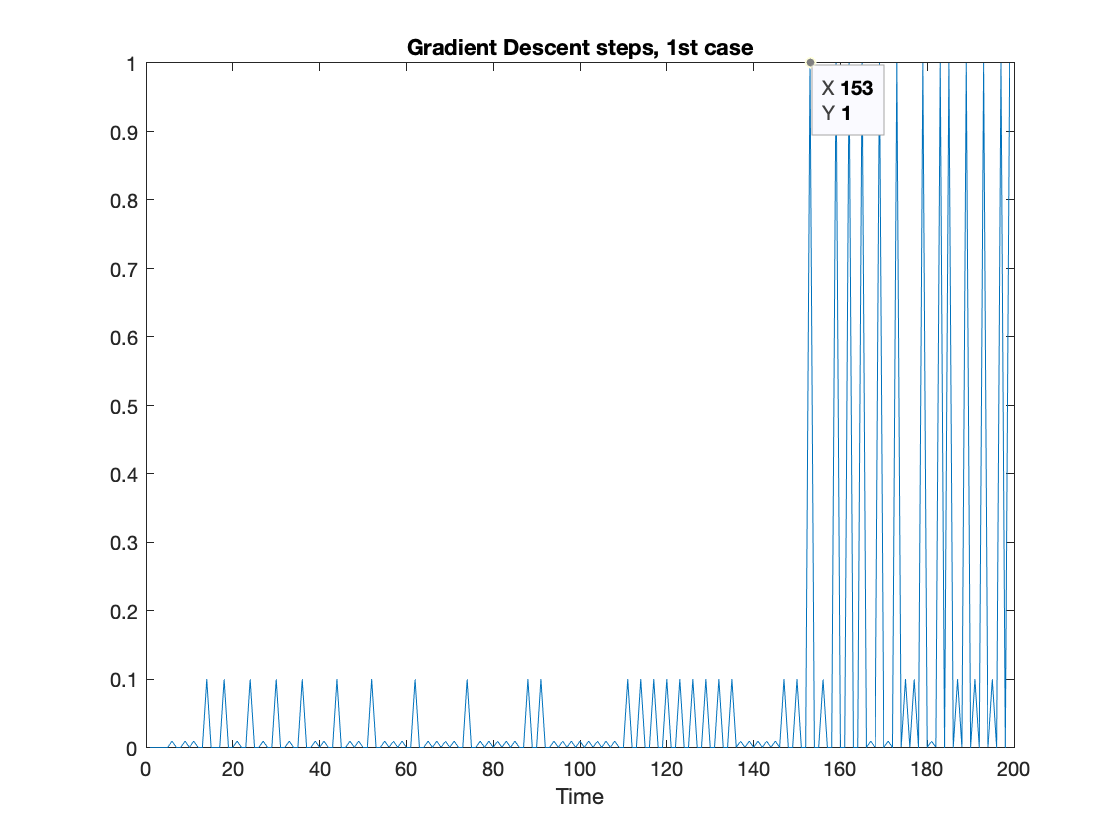

plot(steps);xlabel('Time');title('Gradient Descent steps, 1st case');

x1 = 1.2;
x2 = 1.2;
alpha = 1;
c1 = 1e-4;
gamma = 1e-1;
gradients = [];
steps = [];
gradient = 0.1;
while norm(gradient,'inf') > 1e-4
    step = alpha;
    gradient = [-400*(x2-x1^2)*(x1)-2*(1-x1); 200*(x2-x1^2)];
    Hess = [-400*(x2-x1^2)-400*x1*(-2*x1)+2,-400*x1;-400*x1,200];
    gradient = Hess \ gradient;
    newx1 = x1 - step * gradient(1);
    newx2 = x2 - step * gradient(2);
    while objective(newx1, newx2) > objective(x1,x2) + c1 * step * gradient' * -gradient
        step = step * gamma;
        newx1 = x1 - step * gradient(1);
        newx2 = x2 - step * gradient(2);
    end
    x1 = newx1;
    x2 = newx2;
    steps = [steps, step];
    %pause(0.1)
    norm_grad = norm(gradient, "inf");
    gradients = [gradients, norm_grad];
end
x1

x1 = 1.0000

x2

x2 = 1.0000

objective(x1,x2)

ans = 8.7202e-12

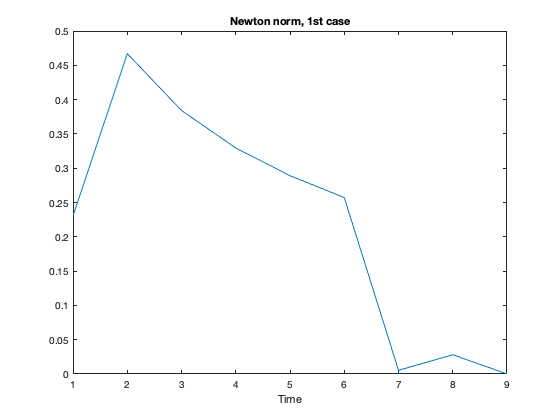

plot(gradients);xlabel('Time');title('Newton norm, 1st case');

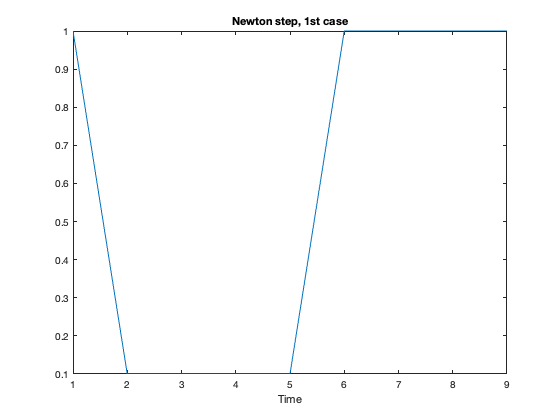

plot(steps);xlabel('Time');title('Newton step, 1st case');